clc; clear;

plane = 1;
dataset = sprintf('bi_hemisphere_plane_%d', plane);
reg_path = sprintf('E:/registration_test/metrics_plane_%d.fig', plane);
reg_ground_truth_path = sprintf('D:/Jeffs LBM paper data/Fig5/20200910/MH184_both_6mm_FOV_150_600um_depth_410mW_9min_no_stimuli/motion_corr_metrics_plane_30.fig');

Run comparison

% Open the figures
gt_data = open(reg_ground_truth_path);

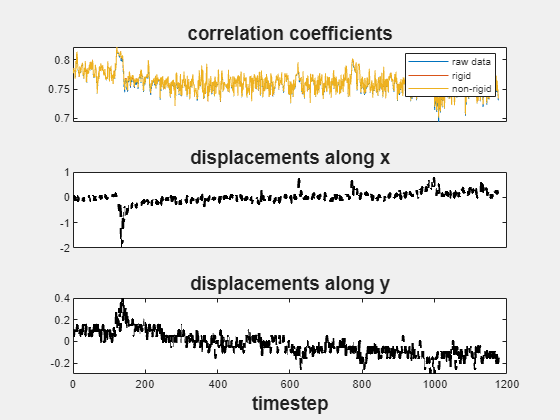

v2_data = open(reg_path);


% Find all axes objects in the figures
gt_axesObjs = findobj(gt_data, 'Type', 'axes');
v2_axesObjs = findobj(v2_data, 'Type', 'axes');

% Ensure there are at least three axes in both figures
if length(gt_axesObjs) < 3 || length(v2_axesObjs) < 3
    error('One or both figures do not contain at least three axes.');
end

% Loop through the second and third axes
for i = 2:3
    if i == 2
        type_xy = "Y";
    else
        type_xy = "X";
    end

    % Find the line objects in the current axis for both datasets
    gt_lineObjs = findobj(gt_axesObjs(i), 'Type', 'line');
    v2_lineObjs = findobj(v2_axesObjs(i), 'Type', 'line');

    % Extract the X and Y data from the first line object in both datasets
    X_gt = get(gt_lineObjs(1), 'XData');
    Y_gt = get(gt_lineObjs(1), 'YData');
    X_v2 = get(v2_lineObjs(1), 'XData');
    Y_v2 = get(v2_lineObjs(1), 'YData');
    Y_diff = Y_gt(:) - Y_v2(:);
    Y_diff = abs(Y_diff);
    
    % Plot the difference for the current axis
    f = figure;
    plot(X_gt, Y_diff);
    title('Difference in pixel shifts: ground truth vs V2');
    xlabel('timestep');
    ylabel = sprintf('Number of Pixels in %s', type_xy);
    grid on;
    fname = sprintf("%s_%d.png", dataset, i);
    saveas(f, fullfile("../../Documents/data/bi_hemisphere/registration/", fname));
end